# Marxian Surplus Value Demo: Lancashire Cotton Mills

Parameters

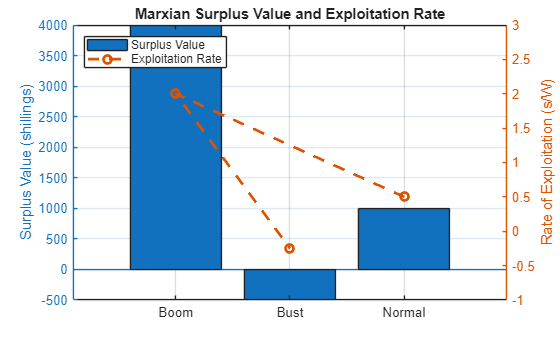

L = 1000;        % number of workers
h = 12;          % hours per day
w = 2;           % wage per worker (shillings)
q = 15;          % output per worker (yards/day)

% Price trajectory: boom then bust
p = [0.2 0.4 0.1];    % shillings per yard

% Compute outputs
Q = L * q;
R = p * Q;             % revenue
W = L * w;             % wage bill
s = R - W;             % surplus value
e = s ./ W;            % exploitation rate

% Plot results
figure;
yyaxis left
bar(categorical({'Normal','Boom','Bust'}), s)
ylabel('Surplus Value (shillings)')
title('Marxian Surplus Value and Exploitation Rate')

yyaxis right
plot(categorical({'Normal','Boom','Bust'}), e, 'o--', 'LineWidth', 2)
ylabel('Rate of Exploitation (s/W)')
ylim([-1 3])

legend('Surplus Value','Exploitation Rate','Location','northwest')
grid on